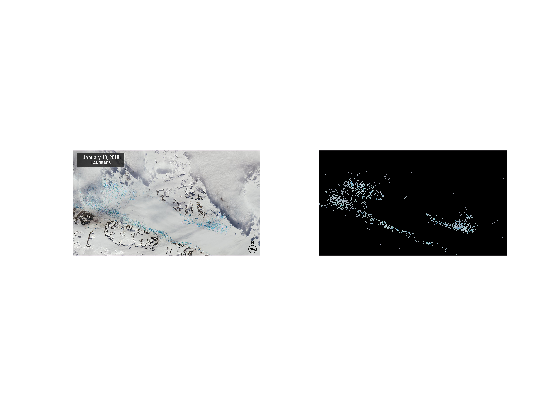

img1 = imread('Data\George VI Ice Shelf\1_SnowPoolsBefore_20180113_md-2048px.jpg');
img2 = imread('Data\George VI Ice Shelf\2_SnowPoolsAfter_20200119_md-2048px.jpg');
[BW1, maskedImg1] = segmentMeltwater(img1);
[BW2, maskedImg2] = segmentMeltwater(img2);
figure(1);
subplot(1,2,1);
imshow(img1);
subplot(1,2,2);
imshow(maskedImg1);

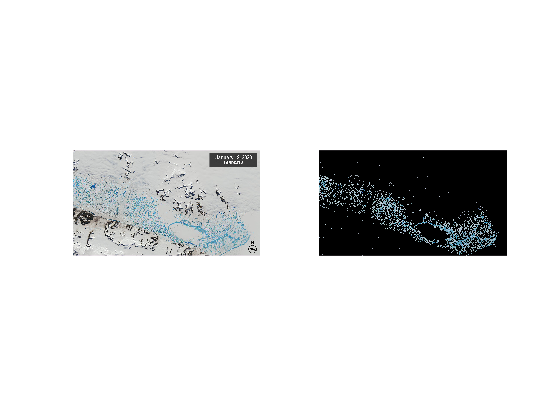

figure(2);
subplot(1,2,1);
imshow(img2);
subplot(1,2,2);
imshow(maskedImg2);

function [BW,maskedRGBImage] = segmentMeltwater(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder App. The colorspace and
%  minimum/maximum values for each channel of the colorspace were set in the
%  App and result in a binary mask BW and a composite image maskedRGBImage,
%  which shows the original RGB image values under the mask BW.

% Auto-generated by colorThresholder app on 12-Aug-2023
%------------------------------------------------------


% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.435;
channel1Max = 0.747;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.141;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.572;
channel3Max = 0.830;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end
